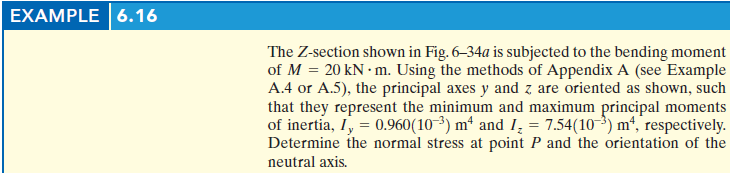

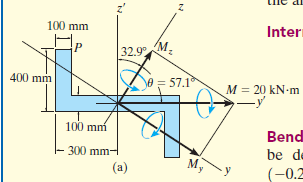

# symbolic units class

u = symunit;

# section properties

% ----------------------
% y-axis centroid
yc = [300-100/2 0 -300+100/2]*u.mm;
Acz = [(400-100)*100 100*600 (400-100)*100]*u.mm^2;
Icz = [(400-100)*100^3 100*600^3 (400-100)*100^3]/sym(12)*u.mm^4;
[yn Qnz Inz] = beam.neutral_axis(yc, Acz, Icz); %#ok
Iz = sum(Inz);
% ----------------------
% z-axis centroid
zc = [(400-100)/2 400-100/2 400+(400-100)/2]*u.mm;
Acy = [100*(400-100) 600*100 100*(400-100)]*u.mm^2;
Icy = [100*(400-100)^3 600*100^3 100*(400-100)^3]/sym(12)*u.mm^4;
[zn Qny Iny] = beam.neutral_axis(zc, Acy, Icy); %#ok
Iy = sum(Iny);
% ----------------------
% product of inertia
Inyz = beam.Iyz(yc, zc, Acz, Icy, Icz);
Iyz = sum(Inyz);
% ----------------------
% principal moments of inertias
[Iyp Izp Iyzp thetap] = beam.Ip(Iy, Iz, Iyz); %#ok
Iyp = Iyp(1);
Izp = Izp(1);
% ----------------------

# normal stress and neutral axis orientation

% ----------------------
% bending moments
M = 20*u.kN*u.m;
Myp = M*sin(thetap(2));
Mzp = M*cos(thetap(2));
% ---------------------
% bending locations
y = (-300+100)*u.mm;
z = (400-100/2)*u.mm;
[yp zp] = beam.xyrot(y, z, thetap(1)); %#ok
% ---------------------
% bending stress and neutral axis orientation
[sigmap alphap] = beam.unsymmetric(Myp, Mzp, Iyp, Izp, yp, zp); %#ok
sigmap = rewrite(sigmap, u.MPa);
sigmap_vpa = vpa(sigmap, 3) %#ok

$$sigmap\_vpa = 3.76\,\mathrm{MPa}$$

alphap_vpa = vpa(alphap, 3) %#ok

$$alphap\_vpa = 85.3\,\deg$$

clear sigmap_vpa alphap_vpa;
% ---------------------